clear
clc

Cg=[0 0 0]       

Cg =      0     0     0


Point_mass = [1 1 1];
Point_loc  = [1 2 3;1 2 3;1 2 3];
Moi.point_mass = moment_of_inertia_point_mass(Point_mass,Point_loc,Cg)

Moi = 包含以下字段的 struct :
    point_mass: [1×1 struct]


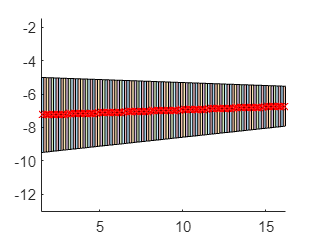

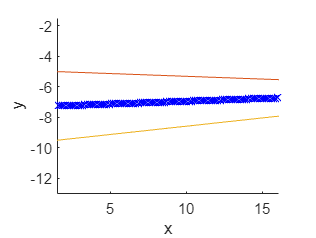

Moi = 包含以下字段的 struct :
    point_mass: [1×1 struct]
          wing: [1×1 struct]



%Wing参数
Wing.aspect = 8.5    ; Wing.sweep_25 = 0    ; Wing.taper    = 0.531;
Wing.croot  = 4.5    ; Wing.span     = 29.4 ; Wing.dihedral = -6.5;
Wing.mass   = 50.6378; Wing.n        = 100  ;%需要多少section
Loc.w_x     = -5     ; Loc.w_y       = 1.5  ; Loc.w_z       = 0;%leading edge root position
Loc.cg      = Cg;
Moi.wing    = moment_of_inertia_lifting_surf(Wing,Loc)

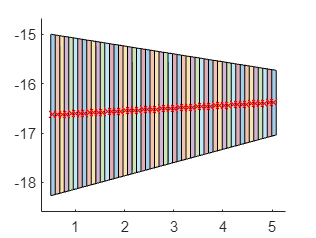

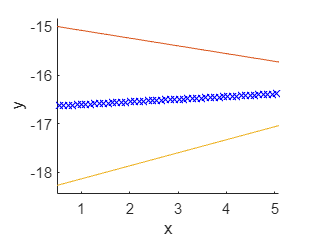

Moi = 包含以下字段的 struct :
    point_mass: [1×1 struct]
          wing: [1×1 struct]
            ht: [1×1 struct]



HT.aspect  = 4      ; HT.sweep_25 = 3    ; HT.taper    = 0.4;
HT.croot   = 3.27   ; HT.span     = 9.17 ; HT.dihedral = 0;
HT.mass    = 50.6378; HT.n        = 50   ; %需要多少section
Loc_ht.w_x = -15    ; Loc_ht.w_y  = 0.5  ; Loc_ht.w_z = 0;%leading edge root position
Loc_ht.cg  = Cg;
Moi.ht     = moment_of_inertia_lifting_surf(HT,Loc_ht)

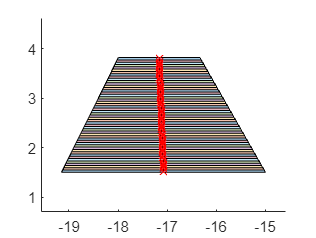

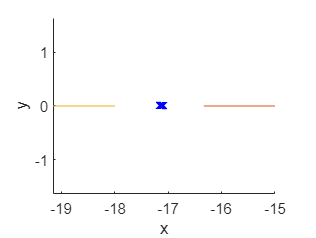

Moi = 包含以下字段的 struct :
    point_mass: [1×1 struct]
          wing: [1×1 struct]
            ht: [1×1 struct]
            vt: [1×1 struct]



VT.aspect  = 8.5     ; VT.sweep_25 = 17   ; VT.taper   = 0.4;
VT.croot   = 4.15    ; VT.span     = 4.65 ; VT.dihedral = 0;
VT.mass    = 50.6378 ; VT.n        = 50   ; %需要多少section
Loc_VT.w_x = -15     ; Loc_VT.w_y  = 0    ; Loc_VT.w_z = 1.5;%leading edge root position
Loc_VT.cg  = Cg;
Moi.vt     = moment_of_inertia_vt(VT,Loc_VT)

function Moi=moment_of_inertia_lifting_surf(Sec,Loc)
Sec.ctip     = Sec.croot*Sec.taper;
Sec.semispan = Sec.span/2;
rollrmatrix=[cosd(Sec.dihedral) 0 sind(Sec.dihedral);0 1 0;-sind(Sec.dihedral) 0 cosd(Sec.dihedral)];

%计算
Loc.LE_R = [Loc.w_x          ;Loc.w_y;Loc.w_z];
Loc.TE_R = [Loc.w_x-Sec.croot;Loc.w_y;Loc.w_z];
Loc.LE_T = [Loc.w_x-1/4*Sec.croot-tand(Sec.sweep_25)*Sec.semispan+1/4*Sec.ctip;Loc.w_y+Sec.semispan;Loc.w_z];
Loc.TE_T = [Loc.w_x-1/4*Sec.croot-tand(Sec.sweep_25)*Sec.semispan-3/4*Sec.ctip;Loc.w_y+Sec.semispan;Loc.w_z];
%为了plot要xy换位置
Loc.LE_cal=[linspace(Loc.LE_R(2),Loc.LE_T(2),Sec.n+1); linspace(Loc.LE_R(1),Loc.LE_T(1),Sec.n+1);zeros(1,Sec.n+1)+Loc.w_z];
Loc.TE_cal=[linspace(Loc.TE_R(2),Loc.TE_T(2),Sec.n+1); linspace(Loc.TE_R(1),Loc.TE_T(1),Sec.n+1);zeros(1,Sec.n+1)+Loc.w_z];

figure
hold on
axis equal

for i=1:size(Loc.LE_cal,2)-1
    shapex_cal = [Loc.LE_cal(1,i),Loc.LE_cal(1,i+1),Loc.TE_cal(1,i+1),Loc.TE_cal(1,i)];
    shapey_cal = [Loc.LE_cal(2,i),Loc.LE_cal(2,i+1),Loc.TE_cal(2,i+1),Loc.TE_cal(2,i)];
    shape_cal  = polyshape(shapex_cal,shapey_cal);
    plot(shape_cal)
    [Loc.cg_x_ws_cal(i),Loc.cg_y_ws_cal(i)] = centroid(shape_cal);
    Loc.cg_ws_cal(:,i)  = [Loc.cg_x_ws_cal(i);Loc.cg_y_ws_cal(i);zeros(1,1)+Loc.w_z];
    Loc.cg_ws_r_cal(:,i)= rollrmatrix*Loc.cg_ws_cal(:,i);%旋转过后
    Sec.chord_mean(i)  = 0.5*(sqrt((Loc.LE_cal(1,i)-Loc.TE_cal(1,i))^2+(Loc.LE_cal(2,i)-Loc.TE_cal(2,i))^2)+sqrt((Loc.LE_cal(1,i+1)-Loc.TE_cal(1,i+1))^2+(Loc.LE_cal(2,i+1)-Loc.TE_cal(2,i+1))^2));
end

Sec.dens = Sec.mass/sum(Sec.chord_mean.^2);

for i=1:size(Loc.LE_cal,2)
    Loc.LE_r_cal(:,i) = rollrmatrix*Loc.LE_cal(:,i);
    Loc.TE_r_cal(:,i) = rollrmatrix*Loc.TE_cal(:,i);
end
plot(Loc.cg_ws_cal(1,:),Loc.cg_ws_cal(2,:),'xr')
hold off

figure
hold on
plot3(Loc.cg_ws_r_cal(1,:),Loc.cg_ws_r_cal(2,:),Loc.cg_ws_r_cal(3,:),'bx')
plot3(Loc.LE_r_cal(1,:)   ,Loc.LE_r_cal(2,:),Loc.LE_r_cal(3,:))
plot3(Loc.TE_r_cal(1,:)   ,Loc.TE_r_cal(2,:),Loc.TE_r_cal(3,:))
axis equal
xlabel('x')
ylabel('y')
zlabel('z')
Loc.cg_ws(1,:)=Loc.cg_ws_r_cal(2,:);
Loc.cg_ws(2,:)=Loc.cg_ws_r_cal(1,:);
Loc.cg_ws(3,:)=Loc.cg_ws_r_cal(3,:);
dx=Loc.cg_ws(1,:)-Loc.cg(1);
dy=Loc.cg_ws(2,:)-Loc.cg(2);
dz=Loc.cg_ws(3,:)-Loc.cg(3);

Moi.ixx=sum(Sec.dens*Sec.chord_mean.^2.*(dy.^2+dz.^2));
Moi.iyy=sum(Sec.dens*Sec.chord_mean.^2.*(dx.^2+dz.^2));
Moi.izz=sum(Sec.dens*Sec.chord_mean.^2.*(dx.^2+dy.^2));
Moi.ixy=sum(Sec.dens*Sec.chord_mean.^2.*(dx.*dy));
Moi.ixz=sum(Sec.dens*Sec.chord_mean.^2.*(dx.*dz));
Moi.iyz=sum(Sec.dens*Sec.chord_mean.^2.*(dy.*dz));
end






function Moi=moment_of_inertia_vt(Sec,Loc)
Sec.ctip     = Sec.croot*Sec.taper;
Sec.semispan = Sec.span/2;

%计算
Loc.LE_R = [Loc.w_x         ;Loc.w_y;Loc.w_z];
Loc.TE_R = [Loc.w_x-Sec.croot;Loc.w_y;Loc.w_z];
Loc.LE_T = [Loc.w_x-1/4*Sec.croot-tand(Sec.sweep_25)*Sec.semispan+1/4*Sec.ctip;Loc.w_y;Loc.w_z+Sec.semispan];
Loc.TE_T = [Loc.w_x-1/4*Sec.croot-tand(Sec.sweep_25)*Sec.semispan-3/4*Sec.ctip;Loc.w_y;Loc.w_z+Sec.semispan];
Loc.LE   = [linspace(Loc.LE_R(1),Loc.LE_T(1),Sec.n+1);zeros(1,Sec.n+1)+Loc.w_y; linspace(Loc.LE_R(3),Loc.LE_T(3),Sec.n+1);];
Loc.TE   = [linspace(Loc.TE_R(1),Loc.TE_T(1),Sec.n+1);zeros(1,Sec.n+1)+Loc.w_y; linspace(Loc.TE_R(3),Loc.TE_T(3),Sec.n+1);];
figure
hold on
axis equal

for i=1:size(Loc.LE,2)-1
    shapex = [Loc.LE(1,i),Loc.LE(1,i+1),Loc.TE(1,i+1),Loc.TE(1,i)];
    shapey = [Loc.LE(3,i),Loc.LE(3,i+1),Loc.TE(3,i+1),Loc.TE(3,i)];
    shape  = polyshape(shapex,shapey);
    plot(shape)
    [Loc.cg_x_ws(i),Loc.cg_z_ws(i)] = centroid(shape);
    Loc.cg_ws(:,i)  = [Loc.cg_x_ws(i);zeros(1,1)+Loc.w_y;Loc.cg_z_ws(i)];
    Sec.chord_mean(i)  = 0.5*(sqrt((Loc.LE(1,i)-Loc.TE(1,i))^2+(Loc.LE(3,i)-Loc.TE(3,i))^2)+sqrt((Loc.LE(1,i+1)-Loc.TE(1,i+1))^2+(Loc.LE(3,i+1)-Loc.TE(3,i+1))^2));
end

Sec.dens = Sec.mass/sum(Sec.chord_mean.^2);

plot(Loc.cg_ws(1,:),Loc.cg_ws(3,:),'xr')
hold off

figure
hold on
plot3(Loc.cg_ws(1,:),Loc.cg_ws(2,:),Loc.cg_ws(3,:),'bx')
plot3(Loc.LE(1,:)   ,Loc.LE(2,:),Loc.LE(3,:))
plot3(Loc.TE(1,:)   ,Loc.TE(2,:),Loc.TE(3,:))
axis equal
xlabel('x')
ylabel('y')
zlabel('z')
dx=Loc.cg_ws(1,:)-Loc.cg(1);
dy=Loc.cg_ws(2,:)-Loc.cg(2);
dz=Loc.cg_ws(3,:)-Loc.cg(3);

Moi.ixx=sum(Sec.dens*Sec.chord_mean.^2.*(dy.^2+dz.^2));
Moi.iyy=sum(Sec.dens*Sec.chord_mean.^2.*(dx.^2+dz.^2));
Moi.izz=sum(Sec.dens*Sec.chord_mean.^2.*(dx.^2+dy.^2));
Moi.ixy=sum(Sec.dens*Sec.chord_mean.^2.*(dx.*dy));
Moi.ixz=sum(Sec.dens*Sec.chord_mean.^2.*(dx.*dz));
Moi.iyz=sum(Sec.dens*Sec.chord_mean.^2.*(dy.*dz));
end

function Moi=moment_of_inertia_point_mass(Mass,Loc,cg)

dx=Loc(1,:)-cg(1);
dy=Loc(2,:)-cg(2);
dz=Loc(3,:)-cg(3);

Moi.ixx=sum(Mass.*(dy.^2+dz.^2));
Moi.iyy=sum(Mass.*(dx.^2+dz.^2));
Moi.izz=sum(Mass.*(dx.^2+dy.^2));
Moi.ixy=sum(Mass.*(dx.*dy));
Moi.ixz=sum(Mass.*(dx.*dz));
Moi.iyz=sum(Mass.*(dy.*dz));
end